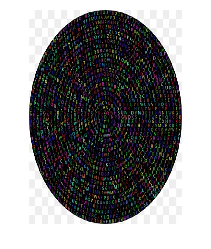

I = imread('img1.jpg');
y = imread('img2.jpg');
I = imresize(I,[700,500]);
imshow(I)

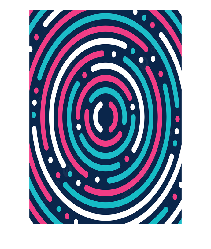

y = imresize(y,[700,500]);
imshow(y)

size(I)

ans =    700   500     3


%I=I(:,:,1)
size(y)

ans =    700   500     3


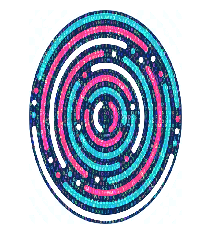

% Adding two images
ImAdd = imadd(I,y);
imshow(ImAdd)

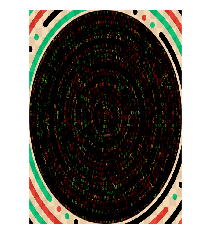

% Subtracting two images
ImSub = imsubtract(I,y);
imshow(ImSub)

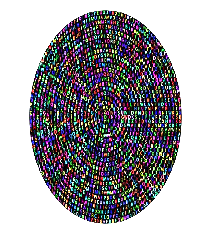

% Multiplying an image with a scalar value
ImMul = immultiply(I,3);
imshow(ImMul)

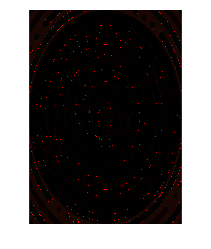

% Dividing one image by another
ImDiv = imdivide(I,y);
imshow(ImDiv)

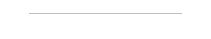

% min values of pixels
minInt = min(I);
imshow(minInt)

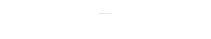

% max values of pixels
maxInt = max(I);
imshow(maxInt)

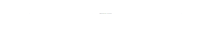

% Contrast calculation
ImContr = maxInt - minInt;
imshow(ImContr)

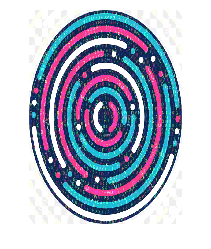

ImU = bitor(I,y);
imshow(ImU)

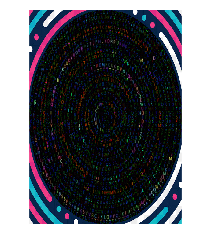

ImI = bitand(I,y);
imshow(ImI)

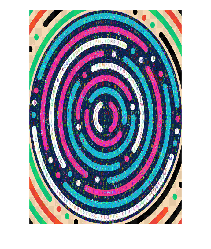

ImX = bitxor(I,y);
imshow(ImX)

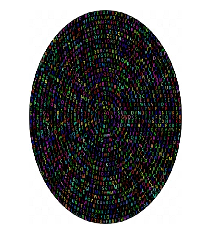

% contrast stretching with median value as threshold value
ImMed = median(I);
contStretch1 = imadjust(I,stretchlim(ImMed),[]);
imshow(contStretch1)

% contrast stretching with mean value as threshold value
ImAvg = mean(I);
contStretch2 = imadjust(I,stretchlim(ImAvg),[]);
imshow(contStretch2)

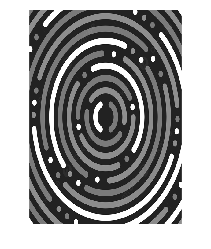

% Converting image to grayscale
I = im2gray(y);
imshow(I)

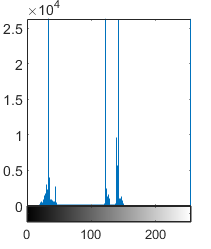

% plotting histogram
imhist(I)

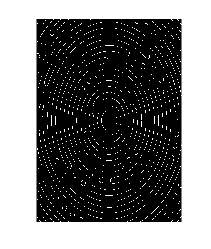

% edge detection
edgedetect = edge(I,'sobel');
imshow(edgedetect)

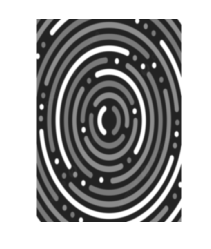

% Smoothing the image
Imblur1 = imgaussfilt(I,2);
Imblur2 = imgaussfilt(I,6);
imshow(Imblur1)

imshow(Imblur2)

%thresholding
I=double(I);
tot=0;
[a,b]=size(I);
y=zeros(a,b);
for i=1:a
    for j=1:b
        tot=tot+I(i,j);
    end
end
tot

tot = 32359210

c= a*b

c = 350000

thr=tot/(a*b)

thr = 92.4549

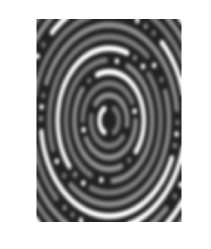

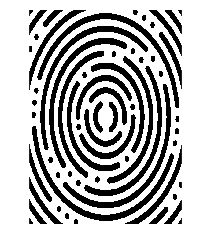

for i=1:a
    for j=1:b
        if I(i,j) > thr
            y(i,j)=0;
        else
            y(i,j)=1;
        end
    end
end
figure;
imshow(y);

% Histogram (own code)
a=imread('img1.jpg');
Gray_Image=im2gray(a);
img_hist = zeros(1,256);
[x,y]=size(Gray_Image)

x = 360

y = 360

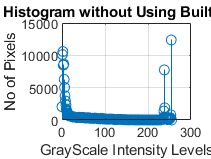

 
for i = 1:x % Rows of Input Image
    for j = 1:y % Colms  of input image
        img_hist(Gray_Image(i,j,1)+1) = img_hist(Gray_Image(i,j,1)+1)+1; %Bin Increment for occurrence
    end
end
figure %Plotting the Histogram
stem(0:255, img_hist); 
grid on;
ylabel('No of Pixels');
xlabel('GrayScale Intensity Levels'); 
title('Image Histogram without Using Built-in Function');

theta=0;
tfiem=rigid2d([cosd(theta) sind(theta);-sind(theta) cosd(theta)],[10,5])

tfiem =   rigid2d with properties:

       Rotation: [2×2 double]
    Translation: [10 5]


ref=imref2d(size(imread("img1.jpg")))

ref =   imref2d with properties:

           XWorldLimits: [0.5000 360.5000]
           YWorldLimits: [0.5000 360.5000]
              ImageSize: [360 360]
    PixelExtentInWorldX: 1
    PixelExtentInWorldY: 1
    ImageExtentInWorldX: 360
    ImageExtentInWorldY: 360
       XIntrinsicLimits: [0.5000 360.5000]
       YIntrinsicLimits: [0.5000 360.5000]


ref.XWorldLimits(2)=ref.XWorldLimits(2)+10

ref =   imref2d with properties:

           XWorldLimits: [0.5000 370.5000]
           YWorldLimits: [0.5000 360.5000]
              ImageSize: [360 360]
    PixelExtentInWorldX: 1.0278
    PixelExtentInWorldY: 1
    ImageExtentInWorldX: 370
    ImageExtentInWorldY: 360
       XIntrinsicLimits: [0.5000 360.5000]
       YIntrinsicLimits: [0.5000 360.5000]


ref.YWorldLimits(2)=ref.YWorldLimits(2)+5

ref =   imref2d with properties:

           XWorldLimits: [0.5000 370.5000]
           YWorldLimits: [0.5000 365.5000]
              ImageSize: [360 360]
    PixelExtentInWorldX: 1.0278
    PixelExtentInWorldY: 1.0139
    ImageExtentInWorldX: 370
    ImageExtentInWorldY: 365
       XIntrinsicLimits: [0.5000 360.5000]
       YIntrinsicLimits: [0.5000 360.5000]


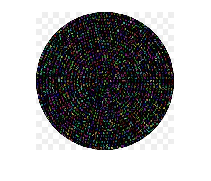

imshow(imwarp(imread("img1.jpg"),tfiem))

translate(I,[10 5])

Check for incorrect argument data type or missing argument in call to function 'translate'.